clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

% IMU parameters
ref_grav    = 9.81;                 % reference gravity  in [m/s2]
ref_omeg    = 1;                    % MEMS reference rotation in [rad/s]

%% call simulation function to 'simulate' and collect the data
amp_acc         = 4;              % [m/s²]
amp_gyro        = 15;             % [deg/s]
f_imu           = 200;            % IMU sample rate in [Hz]
f_acc           = 10;             % [Hz]
t               = 0:1/f_imu:5;    % considered time span for training data; here 50 s
num_train_seq   = 1;             % only one IMU dataset collected for easy adjustments
simulation      = MAIN_SIM_DYN_CALIB(t, f_acc, amp_acc, amp_gyro, ref_grav, num_train_seq);

%% collected data from simulation
%% gyroscope values
g_xup     = simulation.g_xup;

%% accelerometer values
a_xup     = simulation.acc_xup;

%% Deterministic and Stochastic errors
bias_gyro           = simulation.bias_gyro;
bias_acc            = simulation.bias_acc;
SF_gyro             = simulation.SF_gyro;
SF_acc              = simulation.SF_acc;
VRW                 = simulation.VRW;
ARW                 = simulation.ARW;

% % Split the data into training and testing sets
split_ratio             = 0.6; % 60% training, 20% validation, 20% testing
num_samples             = size(a_xup, 1);
split_idx_train         = round(split_ratio * num_samples);
split_idx_val           = round(0.8 * num_samples);

%% reference data from dynamic simulation and Expand reference data 
% 'labels' to be same size as the training & change to cell
acc_ref             = simulation.acc_reference;
labels_grav         = repmat(acc_ref,1,num_train_seq);
gyr_ref             = simulation.gyro_reference;
labels_omeg         = repmat(gyr_ref,1,num_train_seq);


%% split the data to training, validation and testing, including the reference data
%% Training sets
train_data_gyr      = num2cell(g_xup(1:split_idx_train, :),1);
train_data_acc      = num2cell(a_xup(1:split_idx_train, :),1);
train_labels_omeg   = num2cell(labels_omeg(1:split_idx_train, :),1);
train_labels_grav   = num2cell(labels_grav(1:split_idx_train, :),1);

%% Validation sets
val_data_gyr        = num2cell(g_xup(split_idx_train+1:split_idx_val, :),1);
val_data_acc        = num2cell(a_xup(split_idx_train+1:split_idx_val, :),1);
val_labels_omeg     = num2cell(labels_omeg(split_idx_train+1:split_idx_val, :),1);
val_labels_grav     = num2cell(labels_grav(split_idx_train+1:split_idx_val, :),1);

%% Testing sets
test_data_gyr       = num2cell(g_xup(split_idx_val+1:end, :),1);
test_data_acc       = num2cell(a_xup(split_idx_val+1:end, :),1);
test_labels_omeg    = num2cell(labels_omeg(split_idx_val+1:end, :),1);
test_labels_grav    = num2cell(labels_grav(split_idx_val+1:end, :),1);

%% since I need my input size to the NN to be 1, I need to change the
%% appearance of the cell array, where each cell of both data & labels
%% to be 1xsplit_idx & 1xsplit_id+1:end respectively

for k = 1:num_train_seq
    train_data_gyr{k}       = train_data_gyr{k}';
    train_data_acc{k}       = train_data_acc{k}';
    train_labels_omeg{k}    = train_labels_omeg{k}';
    train_labels_grav{k}    = train_labels_grav{k}';
    
    val_data_gyr{k}         = val_data_gyr{k}';
    val_data_acc{k}         = val_data_acc{k}';
    val_labels_omeg{k}      = val_labels_omeg{k}';
    val_labels_grav{k}      = val_labels_grav{k}';
        
    test_data_gyr{k}        = test_data_gyr{k}';
    test_data_acc{k}        = test_data_acc{k}';
    test_labels_omeg{k}     = test_labels_omeg{k}';
    test_labels_grav{k}     = test_labels_grav{k}';
end

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.86 |         0.56 |       0.3674 |       0.1563 |          0.0010 |
|       1 |          50 |       00:00:08 |         0.21 |         0.23 |       0.0222 |       0.0264 |          0.0010 |
|       2 |         100 |       00:00:09 |         0.07 |         0.07 |       0.0026 |       0.0021 |          0.0010 |
|       3 |         150 |       00:00:10 |         0.04 |         0.06 |       0.0007 |       0.0018 |          0.0010 |
|       

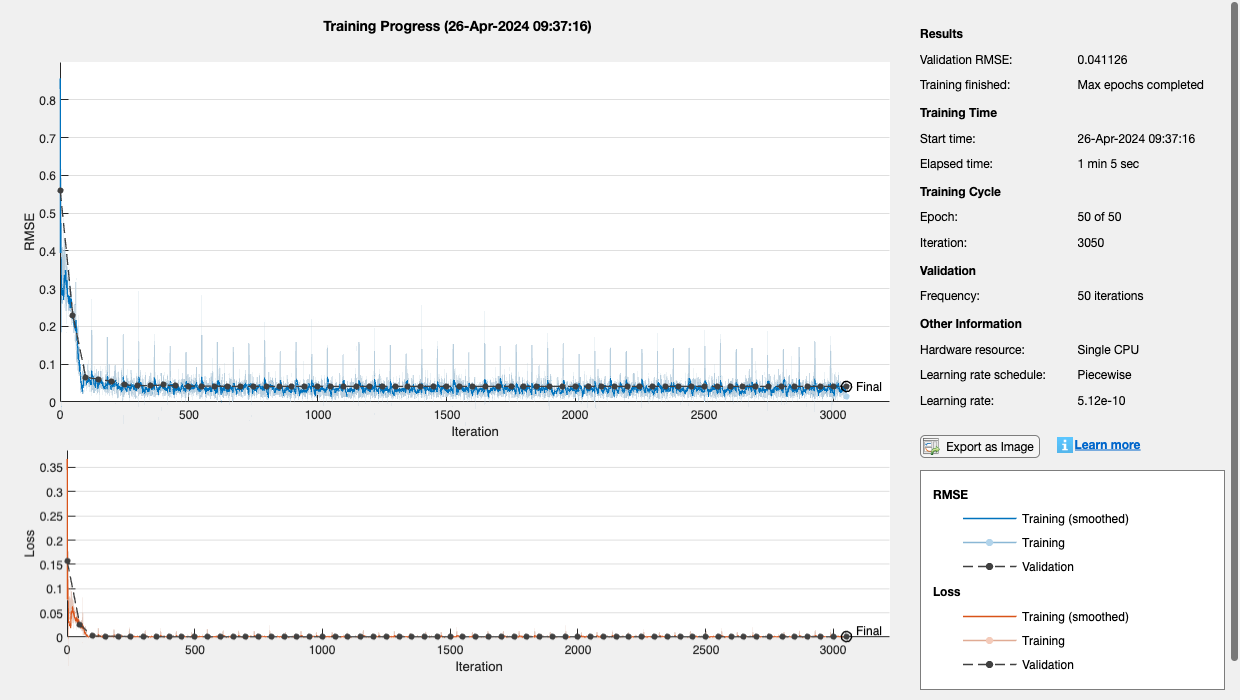

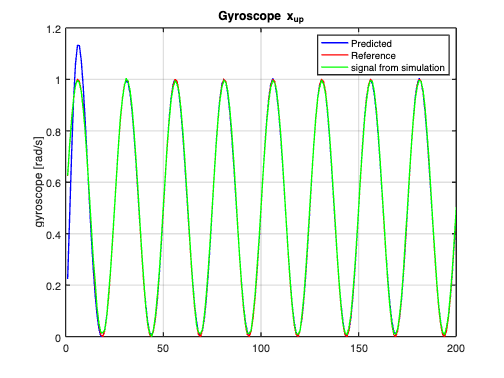

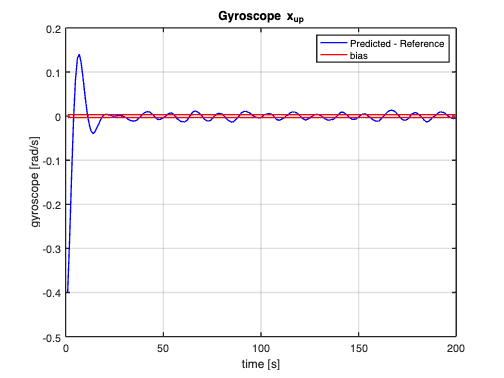

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.80 |         0.53 |       0.3239 |       0.1392 |          0.0010 |
|       1 |          50 |       00:00:04 |         0.15 |         0.18 |       0.0110 |       0.0158 |          0.0010 |
|       2 |         100 |       00:00:05 |         0.07 |         0.05 |       0.0025 |       0.0015 |          0.0010 |
|       3 |         150 |       00:00:06 |         0.04 |         0.05 |       0.0007 |       0.0014 |          0.0010 |
|       

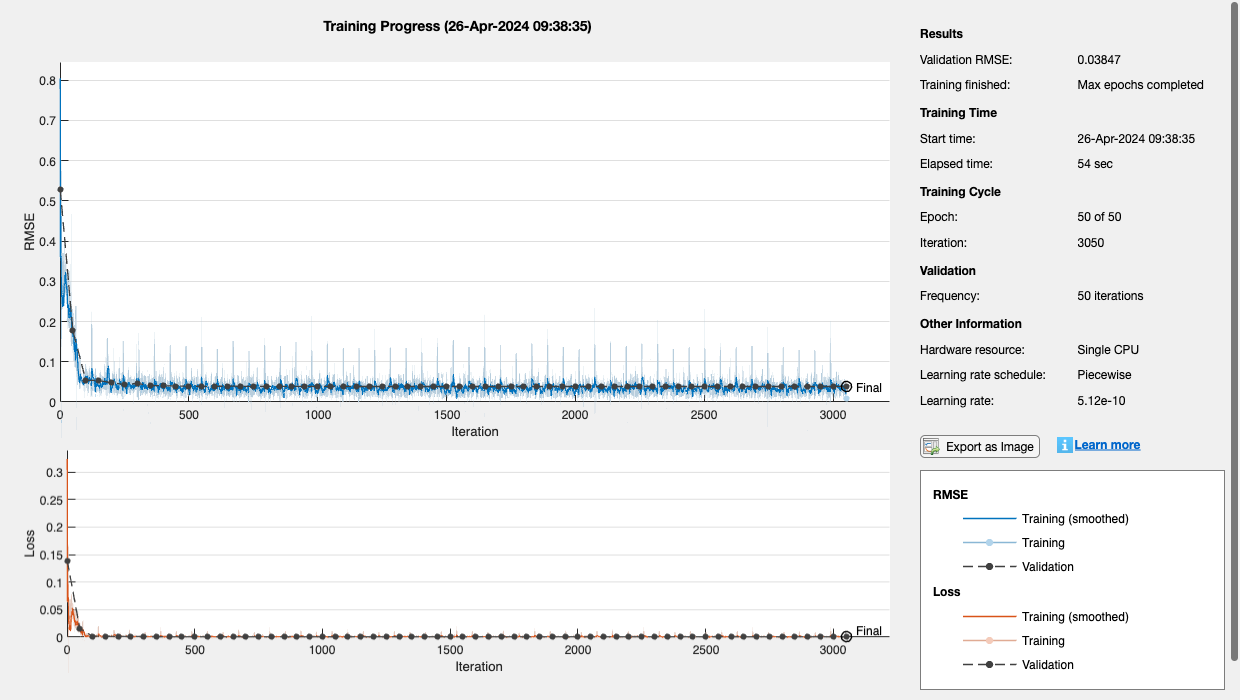

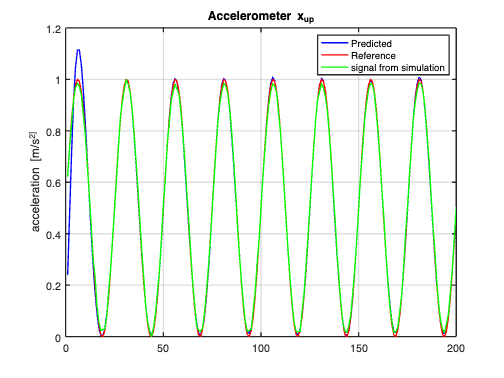

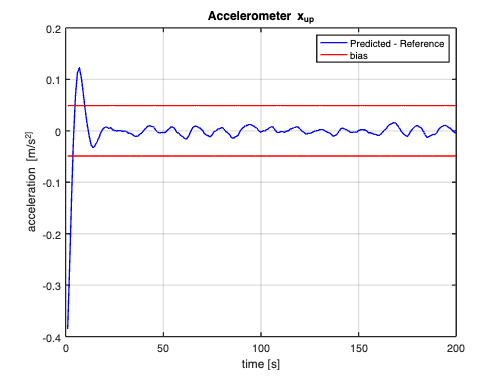

%% Running individual sensors into the NN
for j = 1:2
        if j == 1       % gyroscope data
            train_data     = train_data_gyr;
            train_labels   = train_labels_omeg;

            val_data       = val_data_gyr;
            val_labels     = val_labels_omeg;

            test_data      = test_data_gyr;
            test_labels    = test_labels_omeg;

            % configure neural network (NN)
            numFeatures     = size(train_data, 1); % Number of features in your data
            numHiddenUnits  = 90; % Adjust as needed
            numResponses    = 1;

            layers = [
                sequenceInputLayer(numFeatures)
                lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
                dropoutLayer(0.2)
                tanhLayer
                fullyConnectedLayer(numResponses)
                regressionLayer 
            ];

            % Set training options with the Adam optimizer
            options = trainingOptions('adam', ...
                'MaxEpochs', 50, ...
                'MiniBatchSize', 2^10, ...
                'SequenceLength', 10, ... % Adjust as needed
                'GradientThreshold', 1, ...
                'InitialLearnRate', 0.001, ...
                'LearnRateSchedule', 'piecewise', ...
                'LearnRateDropFactor', 0.2, ...
                'LearnRateDropPeriod', 5, ...
                'ValidationData', {val_data, val_labels}, ...
                'Shuffle', 'every-epoch', ...  % to reduce biases in training
                'ExecutionEnvironment', 'auto', ...
                'Plots','training-progress',...
                'Verbose',1);

            % Train the LSTM network
            net = trainNetwork(train_data, train_labels, layers, options);

            % Test the trained network
            predicted_labels = predict(net, test_data);
            predicted_labels = predicted_labels';

            % PLOTS
            % plot for gyroscope
            aa_g = g_xup(split_idx_train+1:split_idx_val,1);
            aa_g = aa_g';
            fig1=figure;
            plot(predicted_labels{:,1},'b');
            hold on;
            plot(test_labels{:,1}, 'r');
            plot(aa_g,'g');
            grid on
            % xlabel('time [s]');
            ylabel('gyroscope [rad/s]');
            legend('Predicted','Reference','signal from simulation');
            title('Gyroscope x_u_p');
            exportgraphics(fig1,'Gyroscope x_u_p.png','Resolution',300);
        
            delta_g = predicted_labels{:,1}-test_labels{:,1};
            bias_gyro = repelem(bias_gyro,f_imu);
            fig2=figure;
            plot(delta_g,'b');
            hold on
            plot(bias_gyro,'r');
            plot(-1*bias_gyro,'r');
            grid on
            xlabel('time [s]');
            ylabel('gyroscope [rad/s]');
            legend('Predicted - Reference','bias');
            title('Gyroscope x_u_p');
            exportgraphics(fig2,'Gyroscope Predicted - Reference.png','Resolution',300);

        else            % accelerometer data
            train_data     = train_data_acc;
            train_labels   = train_labels_grav;

            val_data       = val_data_acc;
            val_labels     = val_labels_grav;

            test_data      = test_data_acc;
            test_labels    = test_labels_grav;

            % configure neural network (NN)
            numFeatures     = size(train_data, 1); % Number of features in your data
            numHiddenUnits  = 90; % Adjust as needed
            numResponses    = 1;

            layers = [
                sequenceInputLayer(numFeatures)
                lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
                dropoutLayer(0.2)
                tanhLayer
                fullyConnectedLayer(numResponses)
                regressionLayer 
            ];

            % Set training options with the Adam optimizer
            options = trainingOptions('adam', ...
                'MaxEpochs', 50, ...
                'MiniBatchSize', 2^10, ...
                'SequenceLength', 10, ... % Adjust as needed
                'GradientThreshold', 1, ...
                'InitialLearnRate', 0.001, ...
                'LearnRateSchedule', 'piecewise', ...
                'LearnRateDropFactor', 0.2, ...
                'LearnRateDropPeriod', 5, ...
                'ValidationData', {val_data, val_labels}, ...
                'Shuffle', 'every-epoch', ...  % to reduce biases in training
                'ExecutionEnvironment', 'auto', ...
                'Plots','training-progress',...
                'Verbose',1);

            % Train the LSTM network
            net = trainNetwork(train_data, train_labels, layers, options);

            % Test the trained network
            predicted_labels = predict(net, test_data);
            predicted_labels = predicted_labels';

            % PLOTS
            % plot for accelerometer
            aa_a = a_xup(split_idx_train+1:split_idx_val,1);
            aa_a = aa_a';
            fig3=figure;
            plot(predicted_labels{:,1},'b');
            hold on;
            plot(test_labels{:,1}, 'r');
            plot(aa_a,'g');
            grid on
            % xlabel('time [s]');
            ylabel('acceleration [m/s^2]');
            legend('Predicted','Reference','signal from simulation');
            title('Accelerometer x_u_p');
            exportgraphics(fig3,'Accelerometer z_u_p.png','Resolution',300);
        
            delta_a = predicted_labels{:,1}-test_labels{:,1};
            bias_acc = repelem(bias_acc,f_imu);
            fig4=figure;
            plot(delta_a,'b');
            hold on
            plot(bias_acc,'r');
            plot(-1*bias_acc,'r');
            grid on
            xlabel('time [s]');
            ylabel('acceleration [m/s^2]');
            legend('Predicted - Reference','bias');
            title('Accelerometer x_u_p');
            exportgraphics(fig4,'Accelerometer Predicted - Reference.png','Resolution',300);
        end            
end